## ii.

The Nyquist Theorem for sampling states that: 

In order to avoid aliasing, the sampling frequency Fs must be at least larger or equal to the twice largest frequency component in a signal, i.e., Fs>=fmax*2. Hence if our frequency is Fs the largest frequency we can have in our signal in order to avoid aliasing and to certainly reconstruct the signal  is Fs/2. When the pairs are added up their common period becomes the smallest common multiple of these two values. This can be shown as Tnew = T1*T2/GCD(T1,T2), where GCD is the operator for the greatest common divider. Since T1 and T2 values for this example are not integer values, we can do same operation by finding the GCD of the frequencies. Then Tnew = 1/GCD(f1,f2) and the new common frequency will be Fcommon = 1/Tnew = GCD(f1,f2). Hence the number of samples we must take from the frequency domain will simply be N = Fs/(2*Fnew). If it is not an integer we should choose the next largest integer.

sampling_frequency_div_2 = 500;
amplitude_m = [1 1];
phase_m = [0 0];
total_duration = 0.25;

% First we generate function handles of summed sinusoidals using 
% generator_summed_sinusoids

## Pair 1

% Function handle 1: 100 Hz & 110 Hz;
frequency_m_1 = [100 110];
handle_1 = generate_summed_sinusoidals(2,amplitude_m,frequency_m_1,phase_m);

t = linspace(0,total_duration,2*sampling_frequency_div_2*total_duration) 

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0131    0.0141    0.0151    0.0161    0.0171    0.0181    0.0191    0.0201    0.0211    0.0221    0.0231    0.0241    0.0251    0.0261    0.0271    0.0281    0.0291    0.0301    0.0311    0.0321    0.0331    0.0341    0.0351    0.0361    0.0371    0.0382    0.0392    0.0402    0.0412    0.0422    0.0432    0.0442    0.0452    0.0462    0.0472    0.0482    0.0492


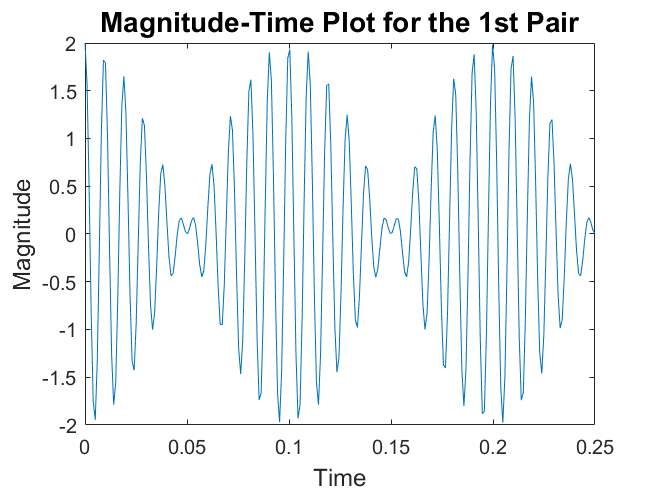


pair_1 = handle_1(t);

figure
plot(t,pair_1);
xlabel('Time','Fontsize',12);
ylabel('Magnitude','Fontsize',12);
title('Magnitude-Time Plot for the 1st Pair','Fontsize',14);
xlim([0 total_duration]);

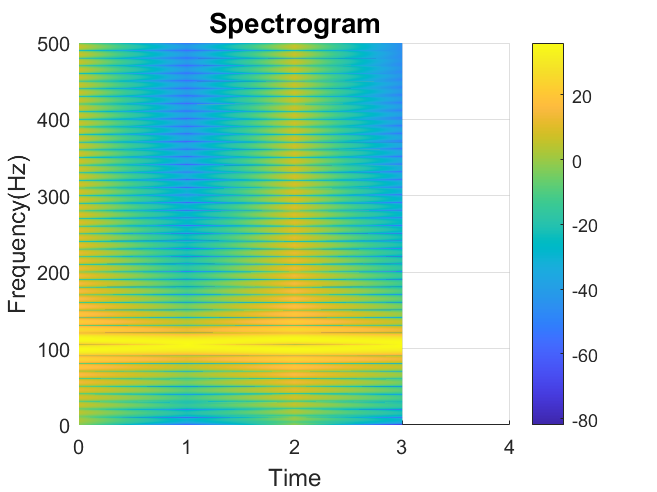


window_length = 100;
window_shift = 50;

figure
spectogram_plotter_generated_signals_vol2(pair_1,window_length,window_shift,'rect',sampling_frequency_div_2)



fcommon = gcd(frequency_m_1(1),frequency_m_1(2));
Tcommon = 1/fcommon;
num_of_samples_needed = sampling_frequency_div_2/fcommon;
disp(['The common period is:', num2str(Tcommon)]);

The common period is:0.1


disp(['The number of samples needed is:', num2str(num_of_samples_needed)]);

The number of samples needed is:50


We can also observe from the time domain signal how the new period is now 0.1 s.

## Pair 2

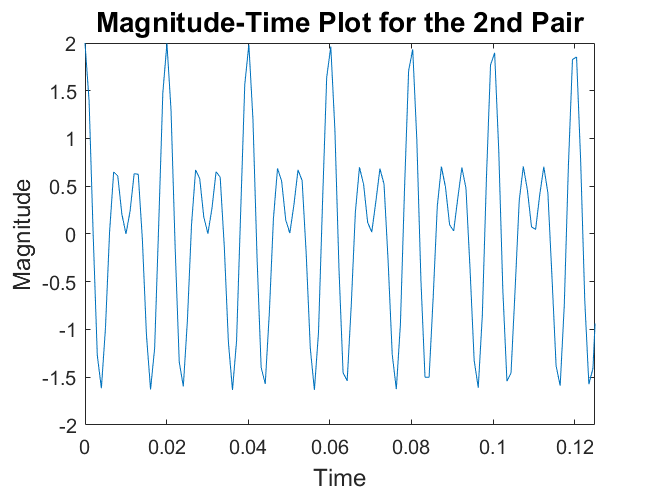

% Function handle 2: 100 Hz & 150 Hz;
frequency_m_2 = [100 150];
handle_2 = generate_summed_sinusoidals(2,amplitude_m,frequency_m_2,phase_m);

t = linspace(0,total_duration,2*sampling_frequency_div_2*total_duration); 

pair_2 = handle_2(t);

figure
plot(t,pair_2);
xlabel('Time','Fontsize',12);
ylabel('Magnitude','Fontsize',12);
title('Magnitude-Time Plot for the 2nd Pair','Fontsize',14);
xlim([0 total_duration/2]);

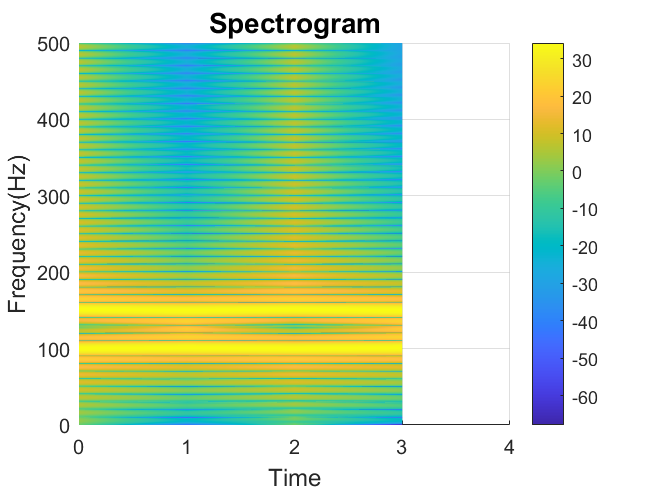


figure
spectogram_plotter_generated_signals_vol2(pair_2,window_length,window_shift,...

    'rectwin',sampling_frequency_div_2)

fcommon = gcd(frequency_m_2(1),frequency_m_2(2));
Tcommon = 1/fcommon;
num_of_samples_needed = sampling_frequency_div_2/fcommon;
disp(['The common period is:', num2str(Tcommon)]);

The common period is:0.02


disp(['The number of samples needed is:', num2str(num_of_samples_needed)]);

The number of samples needed is:10


Again, we can observe from the time plot that the new period is 0.02, just as we calculated using the formula.

## Pair 3

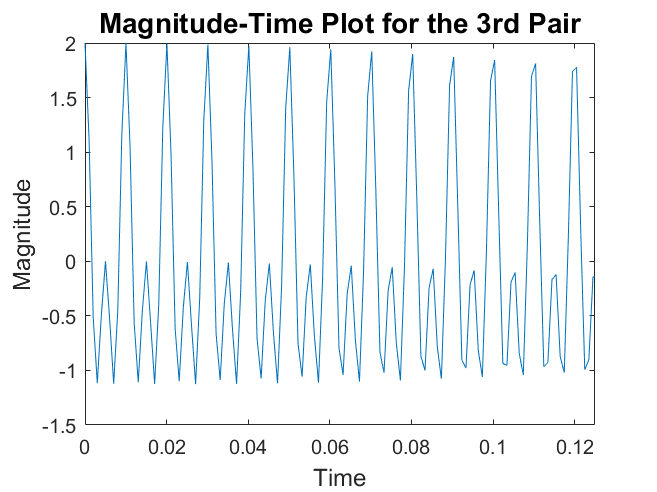

% Function handle 2: 100 Hz & 150 Hz;
frequency_m_3 = [100 200];
handle_3 = generate_summed_sinusoidals(2,amplitude_m,frequency_m_3,phase_m);

t = linspace(0,total_duration,2*sampling_frequency_div_2*total_duration); 

pair_3 = handle_3(t);

figure
plot(t,pair_3);
xlabel('Time','Fontsize',12);
ylabel('Magnitude','Fontsize',12);
title('Magnitude-Time Plot for the 3rd Pair','Fontsize',14);
xlim([0 total_duration/2]);

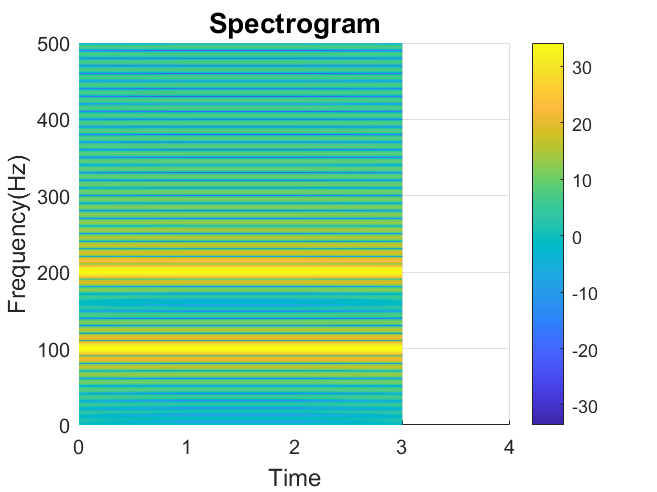


figure
spectogram_plotter_generated_signals_vol2(pair_3,window_length,window_shift,...

    'rectwin',sampling_frequency_div_2)

fcommon = gcd(frequency_m_3(1),frequency_m_3(2));
Tcommon = 1/fcommon;
num_of_samples_needed = sampling_frequency_div_2/fcommon;
disp(['The common period is:', num2str(Tcommon)]);

The common period is:0.01


disp(['The number of samples needed is:', num2str(num_of_samples_needed)]);

The number of samples needed is:5


Again, we can observe from the time plot that the new period is 0.01, just as we calculated using the formula.

Since one of the frequencies is always 100Hz we can use this to analyze better. We see that as the greatest common divider between 100Hz and f2 increases, the common period is lower and he common frequency becomes higher. Thus we'll need less samples to analyze the signal. 

## iii.

We look at the colum frequencies and row frequencies to find the relation in each. It turns out that the ratios between both the column an row frequencies are not linear. For example, the ratio between 697 Hz and 770 Hz is different from the ratio between 770 Hz and 852 Hz. The distance between consecutive signals is also not the same. So there is also not a linearity with an offset.

The varying separation distances between frequencies makes it harder to choose a fixed window size for the STFT. Thus in some cases it becomes hard to effectively capture all DTMF frequencies. For example, if the window size is too small, we might miss lower-frequency components, and if it's too large, it may introduce spectral leakage and affect our identification accuracy. This effect can be seen more clearly in part 2. For instance the value of window length 50 we have chosen for this example succesfully captures the sepeartion between 2nd and 3rd pair while it does not do so well for the 1st pair. 

## iv.

We apply the STFT to the signal in question. The STFT allows us to observe how the frequency content of the signal changes over time. Of course the window size, shift and other parameters should be chosen accordingly. Different parameters may be tried to find the optimal values.

Then we analyze the resulting spectrogram produced by the STFT. Since DTMF signals have distinct frequency pairs associated with each button press, that change over time we first look for the time instances in which these changes appear. After identifying these we determine the frequency pairs in each time interval. 

All that is left to do is to use the table in order to figure it which pairs correspond to which value.

Other alternatives might be:

- Anlayzing in time domain first to identify different singals, and after identifying those intervals taking the Fourier Transform. 

- Goertzel Algoirthm is also one of the commonly used methods for decoding DTMF signals.

- Machine Learnig techniques are also a good alternative that might be useful.